# Lab 2 - 2.

## Init

clear;

## R2.a)

% Upload sound file
[x, Fs] = audioread('How_many_roads.wav');
x = x(1:end-1,1);

% play sampled sound
soundsc(x, Fs);

% stop sound
clear sound

## R2.b)

M = 2048;
xseg = x(48500:48500+M-1);

## R2.c)

N = 1024;
dft = fft(xseg,N);
X=fftshift(2*dft)/M;
f =2*pi*(-N/2:(N-1)/2)'/N;

absX = abs(X);
angX = angle(X);

% Find peaks
[magpks_aux,idxpks_aux] = findpeaks(absX);
for p = 1:3
    [magpks(p), idxpks(p)] = max(magpks_aux);
    magpks_aux(idxpks(p))      = -Inf;
end
idxpks = idxpks_aux(idxpks);
magpks

magpks =     0.0092    0.0058    0.0043


fpks = f(N/2-1+idxpks)

fpks =     0.0184
    0.0368
    0.0552


angpks = angX(N/2-1+idxpks)

angpks =    -0.8207
   -0.8446
    2.9236


## R2.d)

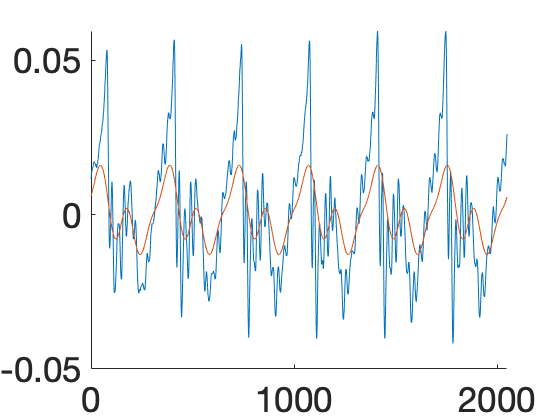

xr = zeros(M,1);
n = (0:M-1)';
for p = 1:3
    xr = xr + magpks(p)*exp(1i*angpks(p))*exp(1i*fpks(p)*n);
    %xr = xr + magpks(p)*cos(angpks(p)+fpks(p)*n);
end 
xr = real(xr);
figure;
hold on;
set(gca,'FontSize',35);
plot(0:M-1,xseg);
plot(0:M-1,xr);

## R2.e)

M = length(x)-1; %% comentario compressao
%% compara size ado sinal antes e depois do dft com S_min
N = M;
dft = fft(x,N);
X = fftshift(2*dft)/M;
f = 2*pi*(-N/2:(N-1)/2)'/N;
absX = abs(X);
angX = angle(X);
magpks = [];
idxpks = [];
% Find peaks
S_min = 1e-4;%1.5e-4;
[magpks_aux,idxpks_aux] = findpeaks(absX(N/2:end));

for p = 1:length(magpks_aux)
    [mag, idx] = max(magpks_aux);
    magpks_aux(idx)      = -Inf;
    if mag > S_min
        magpks(p) = mag;
        idxpks(p) = idx;
    else
        break;
    end
end
size(magpks)

ans =            1        1040



idxpks = idxpks_aux(idxpks);
angpks = angX(round(N/2-1+idxpks'));
fpks = f(round(N/2-1+idxpks'));


xr = zeros(size(x));
n = (0:length(x)-1)';

for p = 1:length(magpks)
    xr = xr + magpks(p)*exp(1i*angpks(p))*exp(1i*fpks(p)*n);
    %xr = xr + magpks(p)*cos(angpks(p)+fpks(p)*n);
end 
xr = real(xr);

% play sampled sound
soundsc(xr, Fs);

% stop sound
clear sound